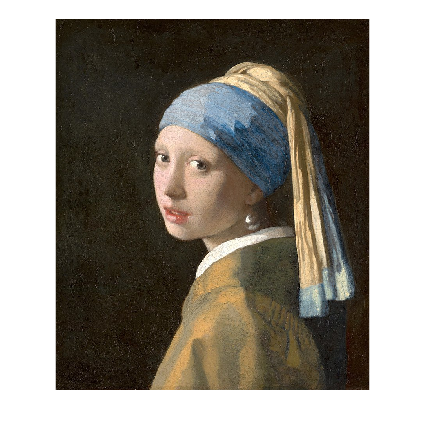

n = 15;
picSize = 30;
load databaseImageCIEs.mat

image = imread("girl.jpg");
imshow(image)

imReproduced = reproduce(image,n,picSize, databaseImageCIEs);
imshow(imReproduced)


load newDatabaseCIEs.mat

imReproduced2 = reproduce(image,n,picSize, newDatabaseCIEs);
imshow(imReproduced2)


newnewDatabaseCIEs = halfOptimize(newDatabaseCIEs);

newnewDatabaseCIEs =    28.9910   11.1538  -16.5035
   39.1811   24.0651   -2.1243
   29.1852   23.7259   22.9036
   17.8986   31.9626   20.4952
   66.2440   -8.2998  -10.8186
   14.4525   32.4753  -15.6938
   56.3323  -30.2170   45.0065
   56.7075   27.3306   34.9797
   35.9005   58.4170  -15.0633
   21.7672    1.5501   -4.9017


imReproduced3 = reproduce(image,n,picSize, newnewDatabaseCIEs);
 imshow(imReproduced3)

CIE =   150.9578  127.9856   80.4778


im = 30×30×3 uint8 array
im(:,:,1) =

    86    59    46    55   128   135    98    46    34    68    72    60    47    27    51    82   111   131   132   127    89    75   104    84    38    53    62    66    47    18
    82    55    56    52   136   126    95    38    34    69    73    64    50    31    51    83   114   132   135   129    87    79   110    85    50    63    65    68    47    18
    75    52    62    57   144   119    94    30    31    68    74    66    54    34    49    81   117   130   143   132    85    88   119    88    68    76    71    69    47    20
    67    58    63    74   147   125    94    29    29    66    74    67    57    36    47    78   115   127   148   136    92   102   125    91    82    85    72    70    50    24
    64    71    61    98   145   135    91    28    22    61    72    68    59    38    42    72   109   123   149   138   104   115   125   100    92    91    73    69    54    31
    63    78    58   110   146   141    89    24    18   

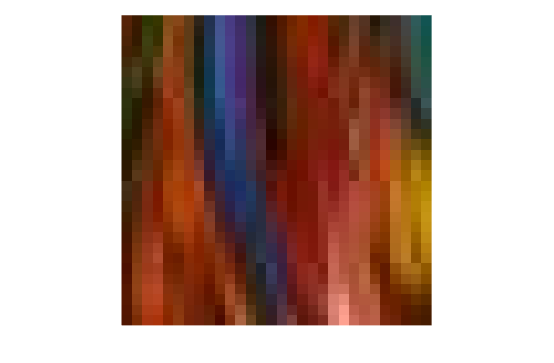

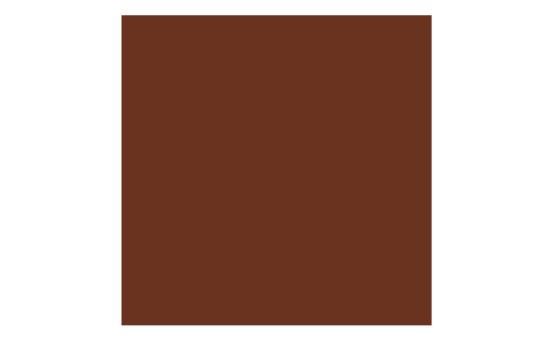

rgb =     0.4300    0.2058    0.1348


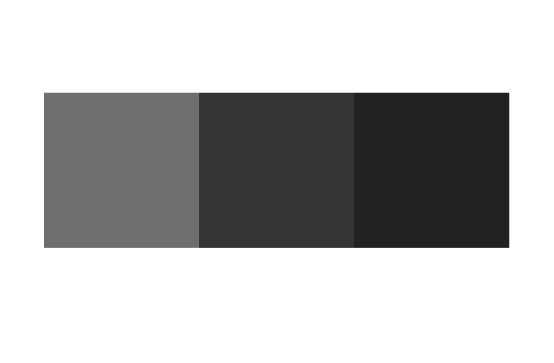

ans =     0.7313    0.3484    0.1541



imCIE = imread("database_rescaled\78.jpg")

    C = mean(imCIE(:,:,1), "all");
    I = mean(imCIE(:,:,2), "all");
    E = mean(imCIE(:,:,3), "all");

    CIE = [C I E]

% clear
% filePattern = fullfile("C:\Users\gayat\Documents\TNM097\Projekt\database", '*.jpg'); 
% theFiles = dir(fullfile("C:\Users\gayat\Documents\TNM097\Projekt\database", '*.jpg'));
% n = 30;
% 
% nrOfImages = length(theFiles);
% 
% for k = 1 : nrOfImages
% 
%     % Load next image
%     baseFileName = theFiles(k).name;
%     fullFileName = fullfile(theFiles(k).folder, baseFileName);
%     Image = im2double(imread(fullFileName));
%     
%     % Resize and save im
%     imSize = size(Image);
%     shorter = imSize(:,2);
%     longer = imSize(:,1);
% 
%     if shorter > longer
%         temp = shorter;
%         shorter = longer;
%         longer = temp;
%     end
% 
%     Image = Image(1:shorter, 1:shorter, :);
% 
%     Image = imresize(Image, [n, n]);
%     imwrite(Image, "database_rescaled\" + baseFileName);
% 
% 
%     % Save CIE value of image
%     CIE = calcCIE(Image);
%     databaseCIE(k,:) = CIE;
% end
% 
% save("databaseCIE", "databaseCIE")

%% Calc CIE for all images
[theFiles, nrOfImages] = loadImageFiles("database_rescaled");
databaseImageCIEs = zeros(nrOfImages,3);
correctIndices = zeros(nrOfImages,1);
for k = 1 : nrOfImages
    % Load next image
    [image, filename] = loadImage(theFiles,k);
    index = str2num(erase(filename,".jpg"));
    databaseImageCIEs(index,:) = calcCIE(image);
end

correctIndices

correctIndices =      1
    10
   100
   101
   102
   103
   104
   105
   106
   107



save("databaseImageCIEs", "databaseImageCIEs")
save("correctIndices", "correctIndices")

newDatabaseCIEs = databaseImageCIEs;
    [~, nrOfImages] = loadImageFiles("database_rescaled");
    
    for i=1:nrOfImages
        currentImCIE = mapCIE(i,:);
        minDist = 10000000;
        for k=(i+1):nrOfImages
            dist = euclideanDist(currentImCIE, newDatabaseCIEs(k,:));
            if dist < minDist
                minDist = dist; 
                ind = k;
            end
        end
        
        newDatabaseCIEs(k,:) = [0 0 0];
        
    end

%%

% OPTIMERING 1 - HALVERA ANTAL BILDER I DATABASEN


function newDatabaseCIEs = halfOptimize(ref) 
    newDatabaseCIEs = ref;
    [~, nrOfImages] = loadImageFiles("database_rescaled");
    
    for i=1:nrOfImages
        currentImCIE = newDatabaseCIEs(i,:);
        minDist = 10000000;
        for k=(i+1):nrOfImages
            dist = euclideanDist(currentImCIE, newDatabaseCIEs(k,:));
            if dist < minDist
                minDist = dist; 
                ind = k;
            end
        end
    
        newDatabaseCIEs(ind,:) = [0 0 0];
        nrOfImages = length(newDatabaseCIEs);
        if nrOfImages == 100
            break
        end
    end






All functions in a script must be closed with an 'end'.